## ***ENME403 Lab with the bois***

clear, close all, clc

**Define system parameters.**

%Constants
m1 = 1.608;      %(kg)       Cart 1 mass 
m2_u = 0.75;     %(kg)       Cart 2 mass unloaded
m3_u = m2_u;     %(kg)       Cart 3 mass unloaded
m2_l = 1.25;     %(kg)       Cart 2 mass loaded 
m3_l = m2_l;     %(kg)       Cart 3 mass loaded
k = 175;         %(N/m)      Spring constant
c1 = 0;          %(Ns/m)     Cart 1 damping
c2 = 3.68;       %(Ns/m)     Cart 2 damping
c3 = c2;         %(Ns/m)     Cart 3 damping
alpha = 12.45;   %(-)        Experimental fiddle factor
R = 1.4;         %(Ohms)     Motor terminal resistance
r = 0.0184;      %(m)        Pinion radius
k_g = 3.71;      %(-)        Gearing ratio
k_m = 0.00176;   %(Vs/rad)   Motor back EMF constant
v_lim = 12;      %(V)        Absolute voltage limit
slew_lim = 30;   %(V/s)      Absolute dv/dt
dx = 0.25;       %(m)         Step size of cart. This could be 0.5

%Matricies
m_matrix = [m1, 0, 0; 0, m2_l, 0; 0, 0, m3_l];
c_matrix = [c1+(k_m^2*k_g^2)/(R*r^2), 0, 0; 0, c2, 0; 0, 0, c3];
k_matrix = [k, -k, 0; -k, 2*k, -k; 0, -k, k];
b_matrix = [(alpha*k_m*k_g)/(R*r); 0; 0];

A = [zeros(3), eye(3); -m_matrix\k_matrix, -m_matrix\c_matrix];
B = [zeros(3,1); m_matrix\b_matrix];
C = [0 0 1 0 0 0]; %[eye(6)];
D = 0;

**State space object**

sys = ss(A, B, C, D);

**Analyse**

CMatrix = ctrb(sys);
OMatrix = obsv(sys);

eig(sys);

Y_U = tf(sys);

[V, E] = eig(A);


**Design control gains**

Pole Method

%poles = [-4+4i -4-4i -6+8i -6-8i -4.1 -7]; %not bad good soize 2.5 sec LAB SET 1 DON'T Touch
poles = [-4.5+6i -4.5-6i -5.5+3i -5.5-3i -6+2.4i -6-2.4i]; %not bad good soize 2.5 sec LAB SET 1 DON'T Touch
%K = place(A, B, poles);

LQR Method

%Q = diag([1, 1, 55, 1, 1, 1]); %Lab set 1 6 seconds
Q = diag([17, 6, 34, 10, 3, 5]); %Lab set 2 6 seconds
R = 10;
K = lqr(sys, Q, R)

K =    -0.3001    1.7608    0.9268    0.8052    0.3310    0.2190


Define System

ACL = A - B*K;
sys = ss(ACL, B, C, D);

%tracking gain N
N = -inv(C*inv(ACL)*B); 

**Responses**

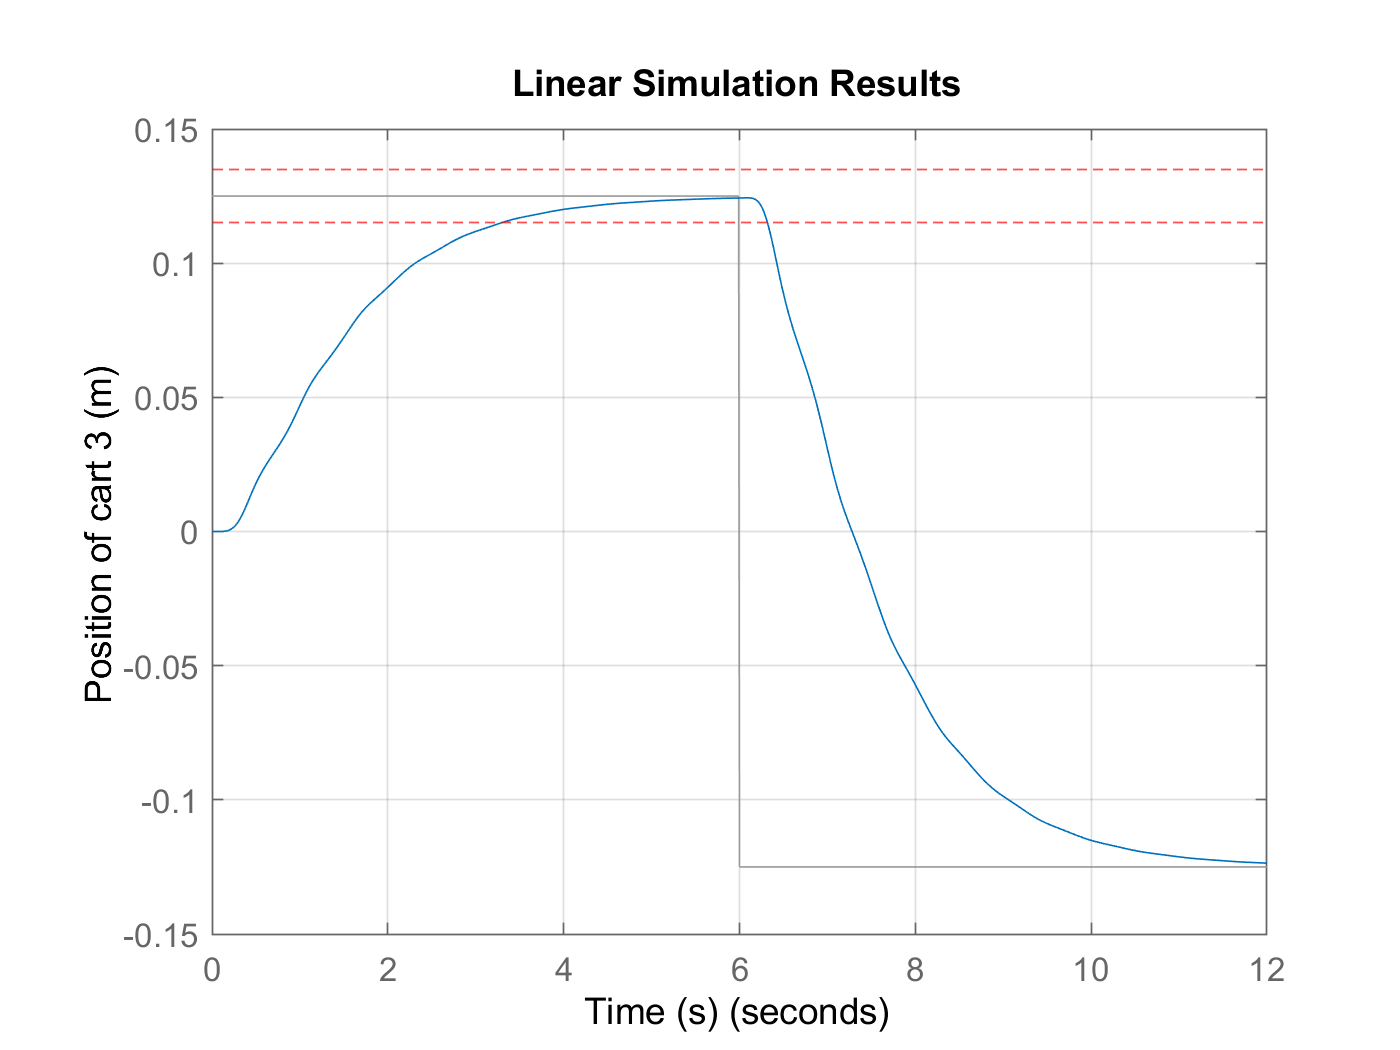

sys.B = N*sys.B; %As it is tracking a dx step input, also include tracking gain N

% Response plot
figure
dt = 0.01;
pulse_duration = 6; %seconds between tracking input steps 2.5sec
num_steps = 2; %number of steps back and forward
tArray = 0:dt:pulse_duration*num_steps; 
rArray = dx/2 .* ones(size(tArray));
for i = 1:2:num_steps-1
    rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1) = -1 * rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1); 
end

lsim(sys, rArray, tArray)
grid on
xlabel('Time (s)')
ylabel('Position of cart 3 (m)')
yline(dx/2+0.01,"--r")
yline(dx/2-0.01,"--r")

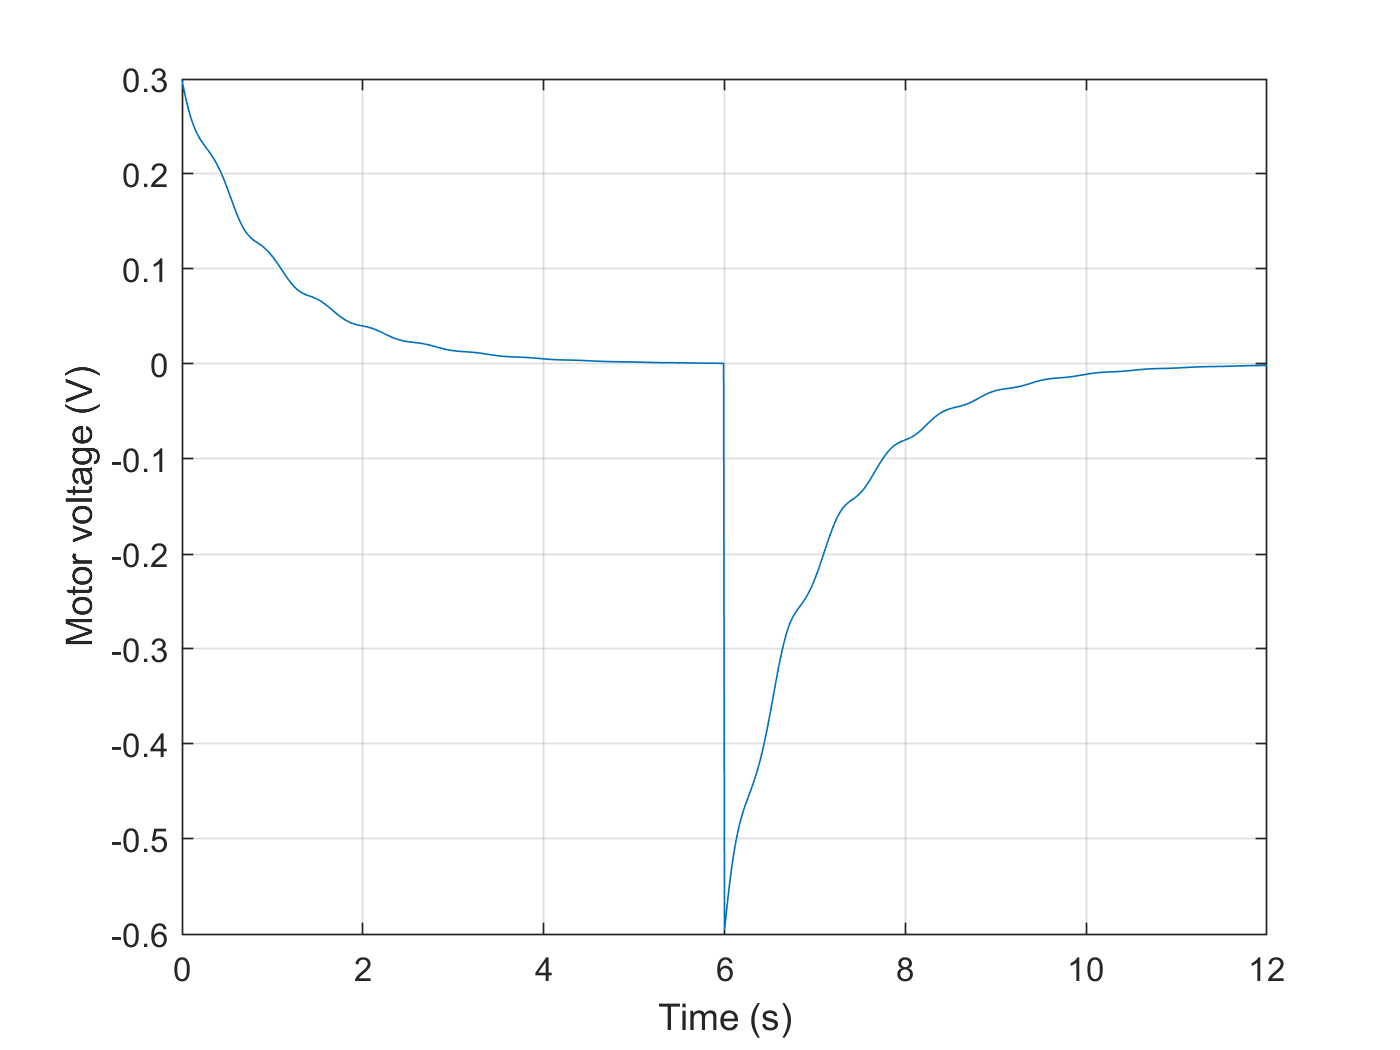


% Voltage
[y, t, x] = lsim(sys, rArray, tArray);
u = -K * x' + N * rArray;


plot(t, u)
grid on
xlabel('Time (s)')
ylabel('Motor voltage (V)')

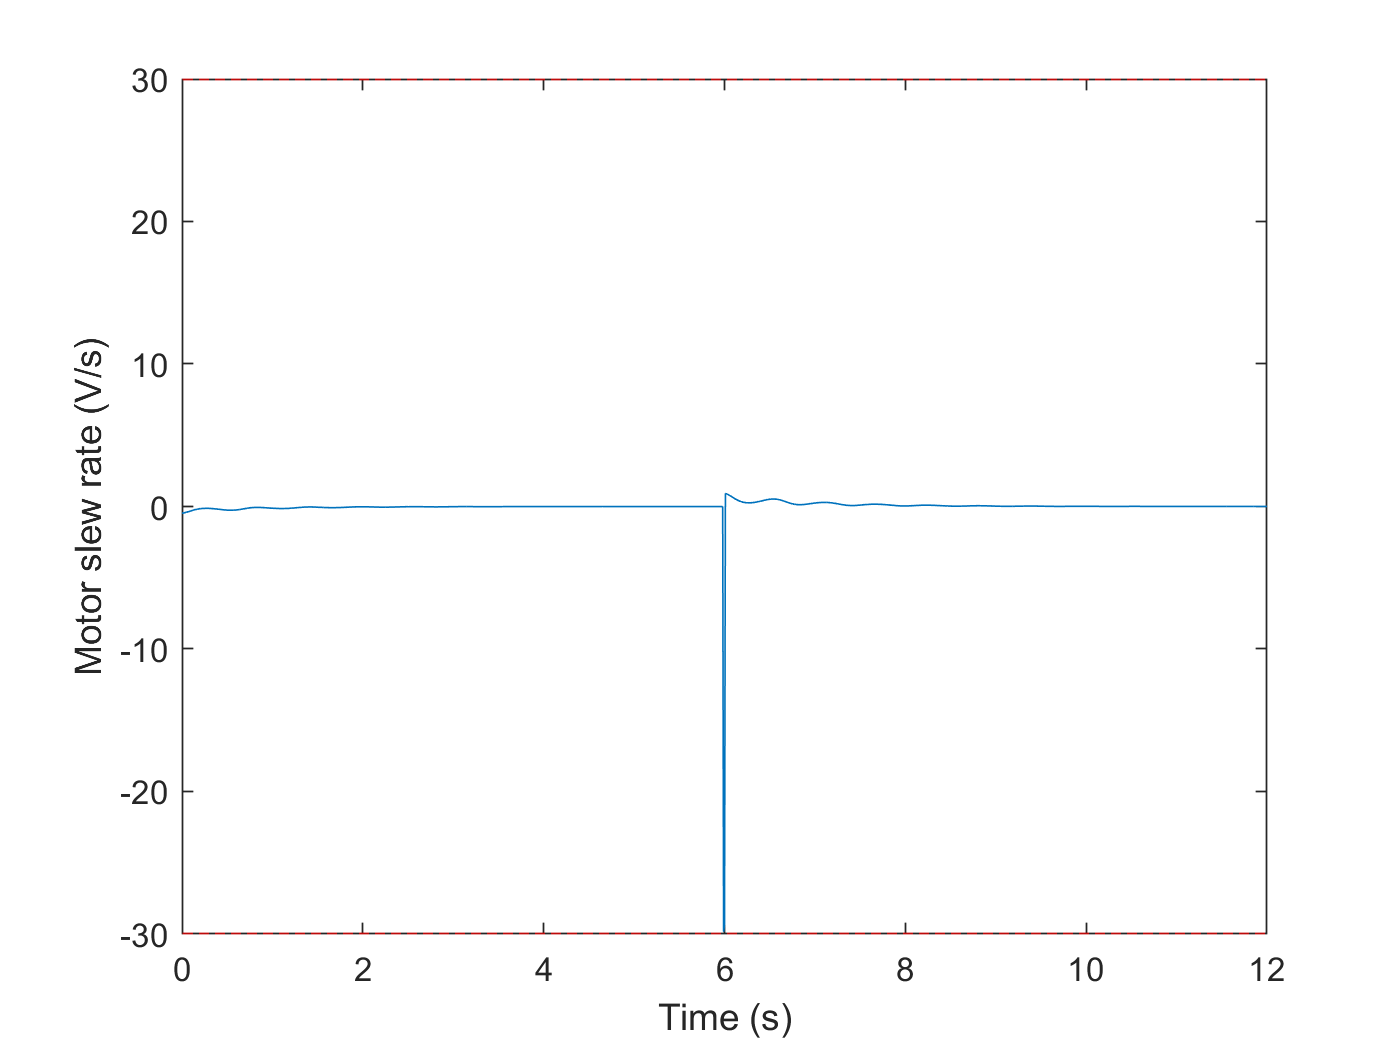


% Slew rate
dudt = gradient(u(:)) ./ gradient(t(:));


figure
plot(t, dudt)

xlabel('Time (s)')
ylabel('Motor slew rate (V/s)')
yline(30,"--r")
yline(-30, "--r")

disp(max(abs(dudt)))

   29.8437



if (max(abs(dudt))>30) 
    fprintf("Warning slow down c*nt %f\n",max(abs(dudt)))
    
end

